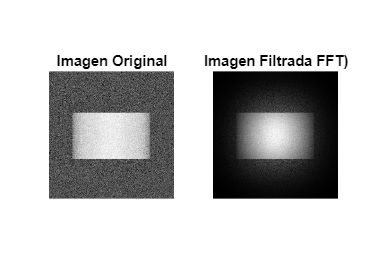

% Lee la imagen
imagen = imread('Fourier2.jpg');

% Convierte la imagen a escala de grises si es a color
if size(imagen, 3) == 3
    imagen_gris = rgb2gray(imagen);
else
    imagen_gris = imagen;
end

% Obtiene el tamaño de la imagen
[m, n] = size(imagen_gris);

% Crea la ventana de Hann en ambas direcciones (filas y columnas)
ventana_hann = hamming(m) * hamming(n)';

% Aplica la ventana de Hann a la imagen
imagen_hann = double(imagen_gris) .* ventana_hann;

% Calcula la FFT de la imagen con ventana de Hann
imagen_fft = fft2(imagen_hann);

% Calcula la IFFT de la imagen FFT
imagen_ifft = ifft2(imagen_fft);

% Muestra la imagen original y la imagen reconstruida
figure;
title("Mejoras de contraste")
subplot(1, 2, 1);
imshow(imagen_gris, []);
title('Imagen Original');

subplot(1, 2, 2);
imshow(abs(imagen_ifft), []);
title('Imagen Filtrada FFT)');

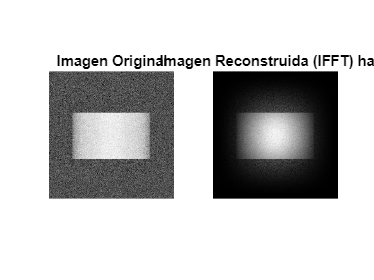

% Lee la imagen
imagen = imread('Fourier2.jpg');

% Convierte la imagen a escala de grises si es a color
if size(imagen, 3) == 3
    imagen_gris = rgb2gray(imagen);
else
    imagen_gris = imagen;
end

% Obtiene el tamaño de la imagen
[m, n] = size(imagen_gris);

% Crea la ventana de Blackman en ambas direcciones (filas y columnas)
ventana_blackman = hann(m) * hann(n)';

% Aplica la ventana de Blackman a la imagen
imagen_blackman = double(imagen_gris) .* ventana_blackman;

% Calcula la FFT de la imagen con ventana de Blackman
imagen_fft = fft2(imagen_blackman);

% Calcula la IFFT de la imagen FFT
imagen_ifft = ifft2(imagen_fft);

% Muestra la imagen original y la imagen reconstruida
figure;
subplot(1, 2, 1);
imshow(imagen_gris, []);
title('Imagen Original');

subplot(1, 2, 2);
imshow(abs(imagen_ifft), []);
title('Imagen Reconstruida (IFFT) hann');

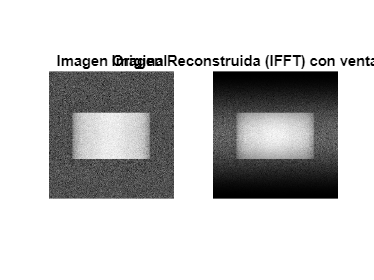

% Lee la imagen
imagen = imread('Fourier2.jpg');

% Convierte la imagen a escala de grises si es a color
if size(imagen, 3) == 3
    imagen_gris = rgb2gray(imagen);
else
    imagen_gris = imagen;
end

% Obtiene el tamaño de la imagen
[m, n] = size(imagen_gris);

% Parámetro de la ventana Tukey
r = 0.5;  % Puedes ajustar este valor entre 0 y 1 (0 es una ventana rectangular, 1 es una ventana de Hann)

% Crea la ventana de Tukey en ambas direcciones (filas y columnas)
ventana_tukey_x = tukeywin(m, 10);
ventana_tukey_y = tukeywin(n, 0.2);

% Ajusta el tamaño de las ventanas para que coincidan con la imagen
ventana_tukey_x = imresize(ventana_tukey_x, [m, 1]);  % Redimensiona la ventana x al tamaño de la imagen
ventana_tukey_y = imresize(ventana_tukey_y, [1, n]);  % Redimensiona la ventana y al tamaño de la imagen

% Crea la ventana de Tukey bidimensional
ventana_tukey = ventana_tukey_x * ventana_tukey_y;

% Aplica la ventana de Tukey a la imagen
imagen_tukey = double(imagen_gris) .* ventana_tukey;

% Calcula la FFT de la imagen con ventana de Tukey
imagen_fft = fft2(imagen_tukey);

% Calcula la IFFT de la imagen FFT
imagen_ifft = ifft2(imagen_fft);

% Muestra la imagen original y la imagen reconstruida
figure;
subplot(1, 2, 1);
imshow(imagen_gris, []);
title('Imagen Original');

subplot(1, 2, 2);
imshow(abs(imagen_ifft), []);
title('Imagen Reconstruida (IFFT) con ventana Tukey');

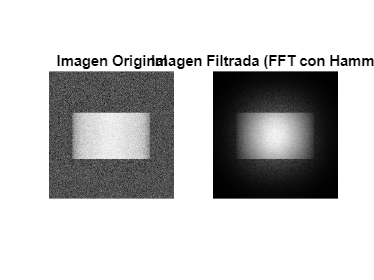

% Lee la imagen
imagen = imread('Fourier2.jpg');

% Convierte la imagen a escala de grises si es a color
if size(imagen, 3) == 3
    imagen_gris = rgb2gray(imagen);
else
    imagen_gris = imagen;
end

% Obtiene el tamaño de la imagen
[m, n] = size(imagen_gris);

% Crea la ventana de Hamming en ambas direcciones (filas y columnas)
ventana_hamming = hamming(m) * hamming(n)';

% Aplica la ventana de Hamming a la imagen
imagen_hamming = double(imagen_gris) .* ventana_hamming;

% Calcula la FFT de la imagen con ventana de Hamming
imagen_fft = fft2(imagen_hamming);

% Calcula la IFFT de la imagen FFT
imagen_ifft = ifft2(imagen_fft);

% Muestra la imagen original y la imagen reconstruida
figure;
title("Mejoras de contraste");
subplot(1, 2, 1);
imshow(imagen_gris, []);
title('Imagen Original');

subplot(1, 2, 2);
imshow(abs(imagen_ifft), []);
title('Imagen Filtrada (FFT con Hamming)');

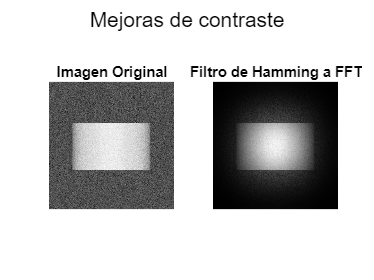

% Lee la imagen
imagen = imread('Fourier2.jpg');

% Convierte la imagen a escala de grises si es a color
if size(imagen, 3) == 3
    imagen_gris = rgb2gray(imagen);
else
    imagen_gris = imagen;
end

% Obtiene el tamaño de la imagen
[m, n] = size(imagen_gris);

% Crea la ventana de Hamming en ambas direcciones (filas y columnas)
ventana_hamming = hamming(m) * hamming(n)';

% Aplica la ventana de Hamming a la imagen
imagen_hamming = double(imagen_gris) .* ventana_hamming;

% Calcula la FFT de la imagen con ventana de Hamming
imagen_fft = fft2(imagen_hamming);

% Calcula la IFFT de la imagen FFT
imagen_ifft = ifft2(imagen_fft);

% Muestra la imagen original y la imagen reconstruida
figure;
sgtitle("Mejoras de contraste");  % Título global

subplot(1, 2, 1);
imshow(imagen_gris, []);
title('Imagen Original');  % Título para la imagen original

subplot(1, 2, 2);
imshow(abs(imagen_ifft), []);
title('Filtro de Hamming a FFT');  % Título para la imagen filtrada

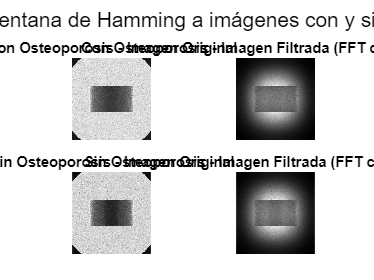

% Lee las imágenes
imagen1 = imread('ConOsteo.png');
imagen2 = imread('SinOsteo.png');

% Convierte las imágenes a escala de grises si es necesario
if size(imagen1, 3) == 3
    imagen_gris1 = rgb2gray(imagen1);
else
    imagen_gris1 = imagen1;
end

if size(imagen2, 3) == 3
    imagen_gris2 = rgb2gray(imagen2);
else
    imagen_gris2 = imagen2;
end

% Obtiene el tamaño de ambas imágenes
[m1, n1] = size(imagen_gris1);
[m2, n2] = size(imagen_gris2);

% Crea la ventana de Hamming para ambas imágenes
ventana_hamming1 = hamming(m1) * hamming(n1)';
ventana_hamming2 = hamming(m2) * hamming(n2)';

% Aplica la ventana de Hamming a ambas imágenes
imagen_hamming1 = double(imagen_gris1) .* ventana_hamming1;
imagen_hamming2 = double(imagen_gris2) .* ventana_hamming2;

% Calcula la FFT y la IFFT para ambas imágenes
imagen_fft1 = fft2(imagen_hamming1);
imagen_ifft1 = ifft2(imagen_fft1);

imagen_fft2 = fft2(imagen_hamming2);
imagen_ifft2 = ifft2(imagen_fft2);

% Muestra las dos imágenes originales y sus versiones filtradas
figure;
sgtitle("Aplicación de ventana de Hamming a imágenes con y sin Osteoporosis");

% Subplot para la primera imagen (ConOsteo.png)
subplot(2, 2, 1);
imshow(imagen_gris1, []);
title('Con Osteoporosis - Imagen Original');

subplot(2, 2, 2);
imshow(abs(imagen_ifft1), []);
title('Con Osteoporosis - Imagen Filtrada (FFT con Hamming)');

% Subplot para la segunda imagen (SinOsteo.png)
subplot(2, 2, 3);
imshow(imagen_gris2, []);
title('Sin Osteoporosis - Imagen Original');

subplot(2, 2, 4);
imshow(abs(imagen_ifft2), []);
title('Sin Osteoporosis - Imagen Filtrada (FFT con Hamming)');

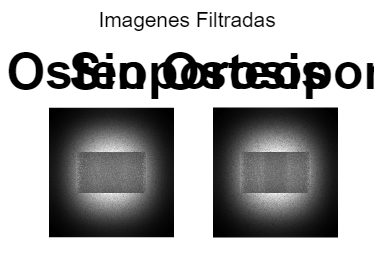

% Lee las imágenes
imagen1 = imread('ConOsteo.png');
imagen2 = imread('SinOsteo.png');

% Convierte las imágenes a escala de grises si es necesario
if size(imagen1, 3) == 3
    imagen_gris1 = rgb2gray(imagen1);
else
    imagen_gris1 = imagen1;
end

if size(imagen2, 3) == 3
    imagen_gris2 = rgb2gray(imagen2);
else
    imagen_gris2 = imagen2;
end

% Obtiene el tamaño de ambas imágenes
[m1, n1] = size(imagen_gris1);
[m2, n2] = size(imagen_gris2);

% Crea la ventana de Hamming para ambas imágenes
ventana_hamming1 = hamming(m1) * hamming(n1)';
ventana_hamming2 = hamming(m2) * hamming(n2)';

% Aplica la ventana de Hamming a ambas imágenes
imagen_hamming1 = double(imagen_gris1) .* ventana_hamming1;
imagen_hamming2 = double(imagen_gris2) .* ventana_hamming2;

% Calcula la FFT y la IFFT para ambas imágenes
imagen_fft1 = fft2(imagen_hamming1);
imagen_ifft1 = ifft2(imagen_fft1);

imagen_fft2 = fft2(imagen_hamming2);
imagen_ifft2 = ifft2(imagen_fft2);

% Muestra las imágenes filtradas en un solo subplot
figure;
sgtitle("Imagenes Filtradas");

% Subplot para la primera imagen (ConOsteo.png)
subplot(1, 2, 1);
imshow(abs(imagen_ifft1), []);
title('Con Osteoporosis','FontSize',30);

% Subplot para la segunda imagen (SinOsteo.png)
subplot(1, 2, 2);
imshow(abs(imagen_ifft2), []);
title('Sin Osteoporosis','FontSize',30);